test_airDensity1             = airDensity([0 1 10 100]);
test_gravityForce1          = gravityForce(1, 9.8);
test_jetForce1               = jetForce(-20, [0; -2e4]);
test_dragForce1              = dragForce([0; 1], 1, linspace(-pi, pi));
test_jetMomentum            = jetMomentum(1, 70 / 2, linspace(-0.01, 0.01));
test_dissipationMomentum1    = rotationDragMomentum(linspace(-1, 1), 1, 1);


test_rocketModel_11 = rocketModel(0, [20e3; 0; 0; 0; 0; 0; 0])

test_rocketModel_11 =   -20.0000
         0
         0
         0
   10.2000
         0
         0


test_rocketModel_1

test_rocketModel_1 =   -20.0000
         0
         0
         0
   10.2000
         0
         0


test_rocketModel_22 = rocketModel(0, [20e3; 0; 0; 0; 100; 0; 0])  % Проверка сил при движении вверх

test_rocketModel_22 =   -20.0000
         0
  100.0000
         0
    5.2000
         0
         0


test_rocketModel_2

test_rocketModel_2 =   -20.0000
         0
  100.0000
         0
    5.2000
         0
         0


test_rocketModel_32 = rocketModel(0, [20e3; 0; 0; 0; 0; 0; 0.1])

test_rocketModel_32 =   -20.0000
         0
         0
         0
   10.2000
    0.1000
   -0.0002


test_rocketModel_3

test_rocketModel_3 =   -20.0000
         0
         0
         0
   10.2000
    0.1000
   -0.0002




u0 = [20e3; 0; 0; 0; 0; 0; 0];
[t, u] = ode89(@rocketModel, [0 600], u0);

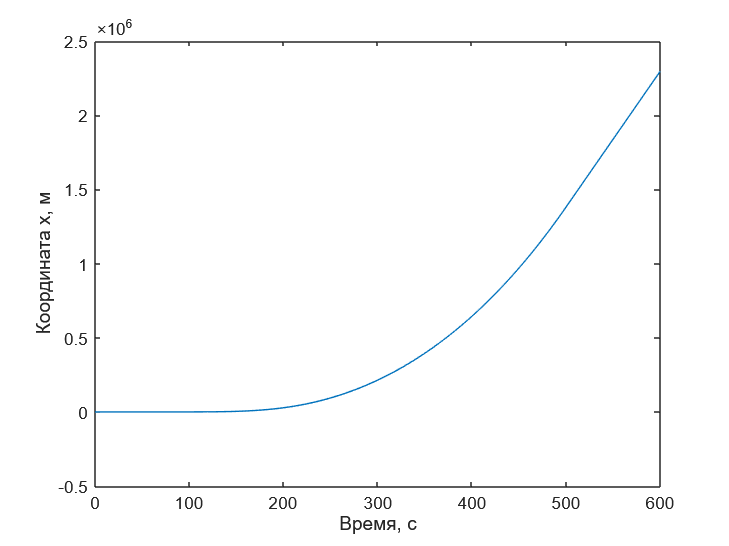



%  Извлечение переменных из решения, представляющего собой матрицу из
%  двух столбцов: y и v
x = u(:,2);
y = u(:,3);
vx = u(:,4);
vy = u(:,5);
v = vx.^2 + vy.^2;
alpha = u(:,6);
omega = u(:,7);
m = u(:,1);

f=figure();
plot(t, x)
xlabel('Время, с')
ylabel('Координата x, м')

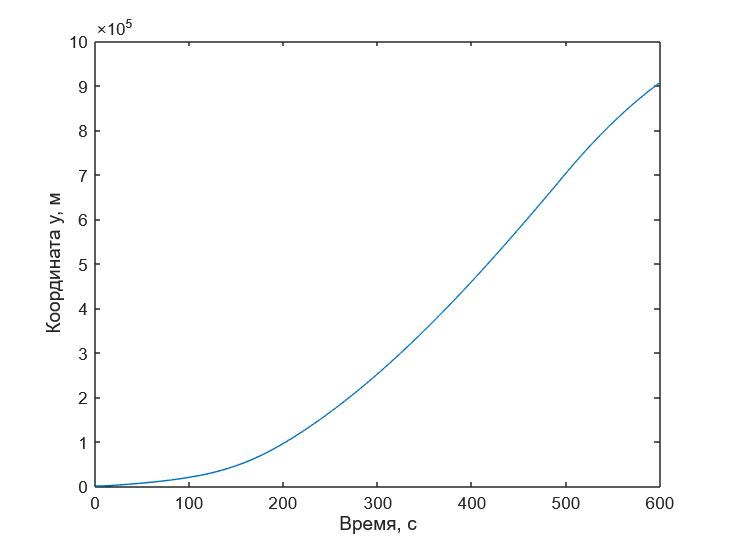


f=figure();
plot(t, y)
xlabel('Время, с')
ylabel('Координата y, м')

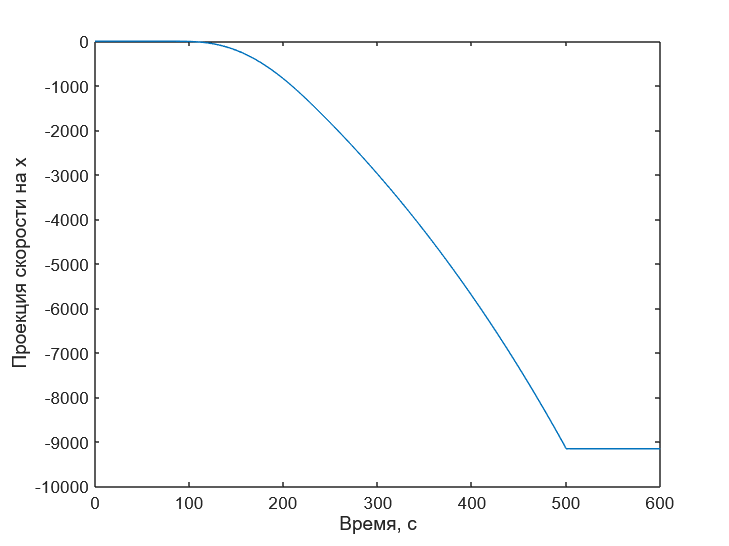


f=figure();
plot(t, vx)
xlabel('Время, с')
ylabel('Проекция скорости на x')

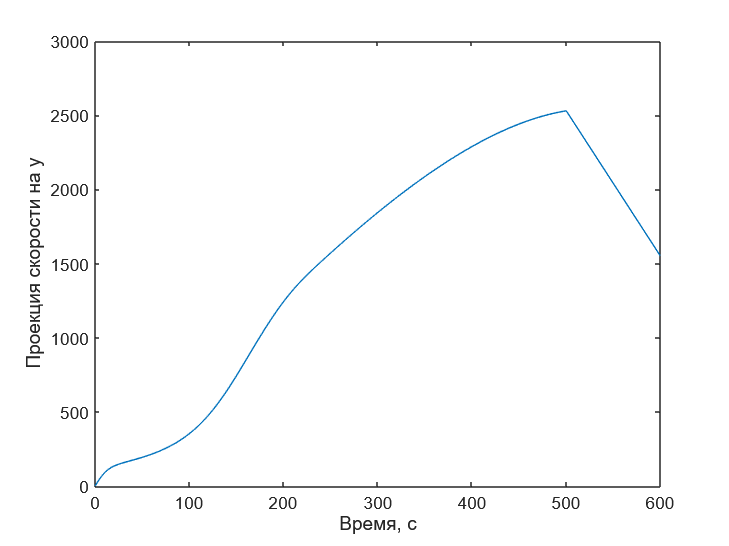


f=figure();
plot(t, vy)
xlabel('Время, с')
ylabel('Проекция скорости на y')

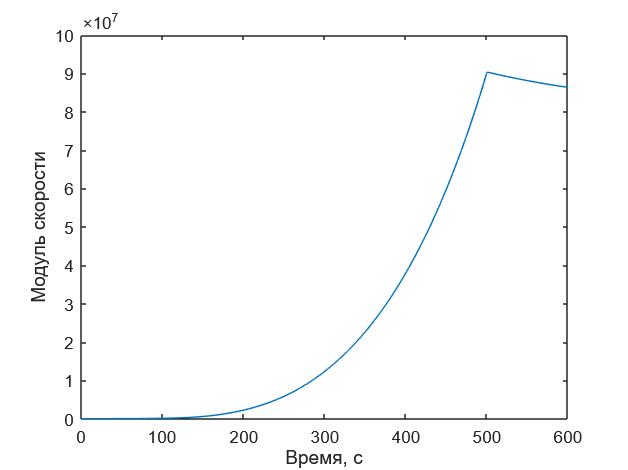


f=figure();
plot(t, v)
xlabel('Время, с')
ylabel('Модуль скорости')

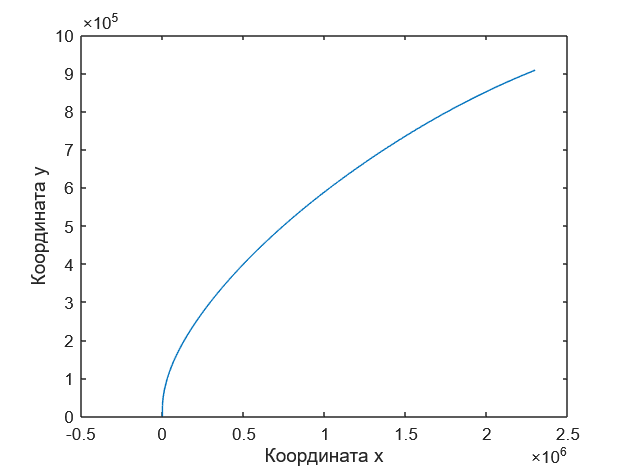


f=figure();
plot(x, y)
xlabel('Координата x')
ylabel('Координата y')

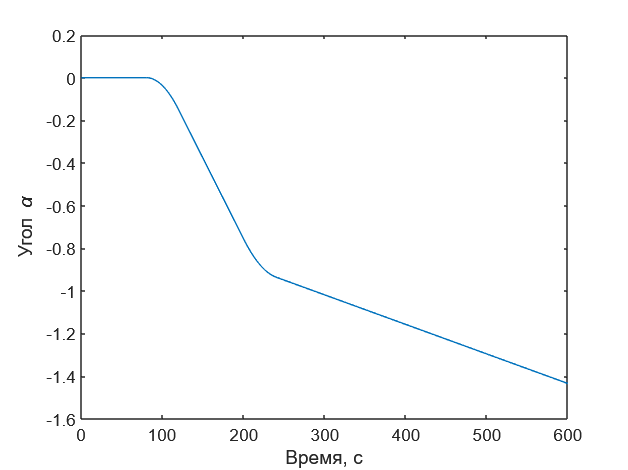


f=figure();
plot(t, alpha)
xlabel('Время, с')
ylabel('Угол \alpha')

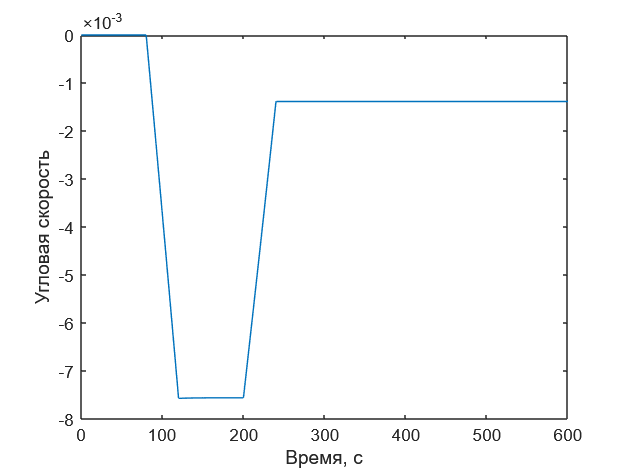


f=figure();
plot(t, omega)
xlabel('Время, с')
ylabel('Угловая скорость')

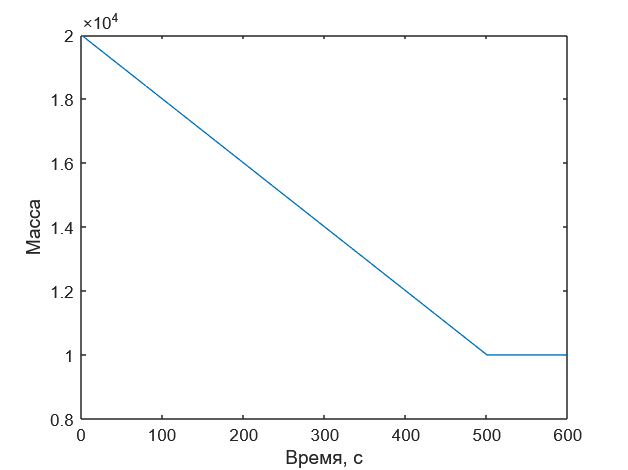


f=figure();
plot(t, m)
xlabel('Время, с')
ylabel('Масса')